**RMSE COMPARISON**

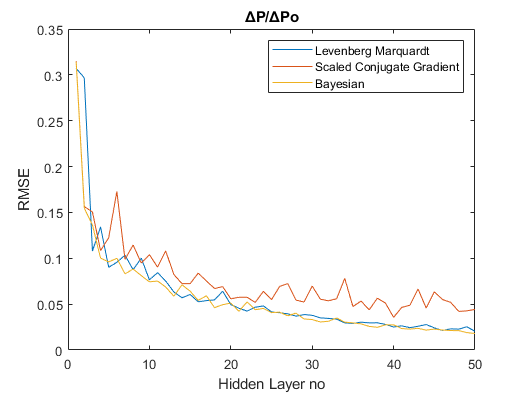

a=figure();
set(gca,'Box','on')
hold on;
plot(1:50,rms_train_lm(:,1));
plot(1:50,rms_train_scg(:,1));
plot(1:50,rms_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(rmse).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

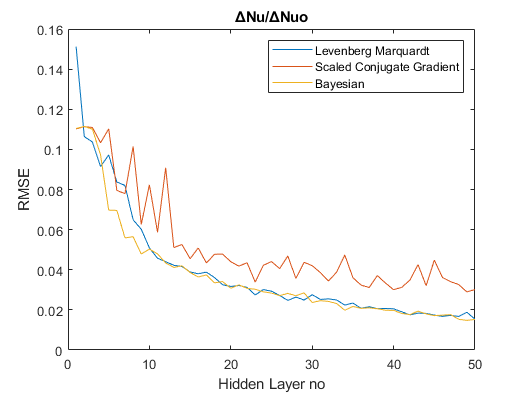


b=figure();
set(gca,'Box','on')
hold on;
plot(1:50,rms_train_lm(:,2));
plot(1:50,rms_train_scg(:,2));
plot(1:50,rms_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(rmse).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**R2 COMPARISON**

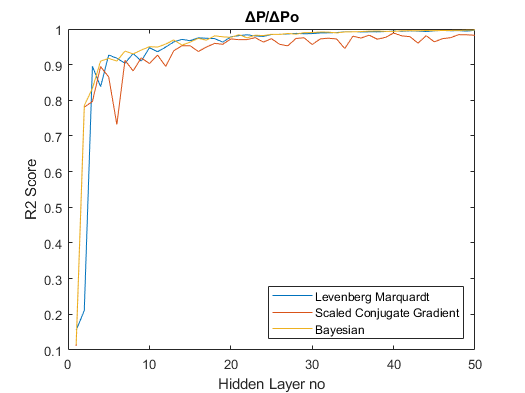

c=figure();
set(gca,'Box','on')
hold on;
plot(1:50,r2_train_lm(:,1));
plot(1:50,r2_train_scg(:,1));
plot(1:50,r2_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('R2 Score')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(r2).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

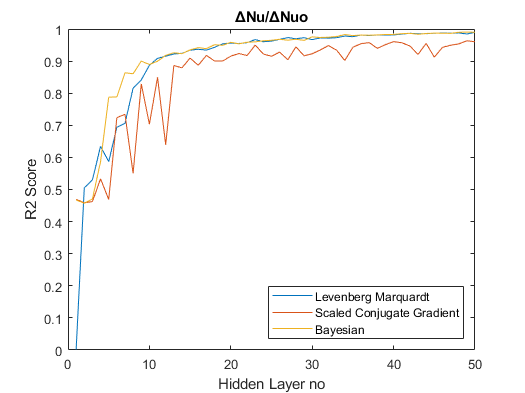


d=figure();
set(gca,'Box','on')
hold on;
plot(1:50,r2_train_lm(:,2));
plot(1:50,r2_train_scg(:,2));
plot(1:50,r2_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('R2 Score')
title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian','location','southeast');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(r2).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**MAPE COMPARISON**

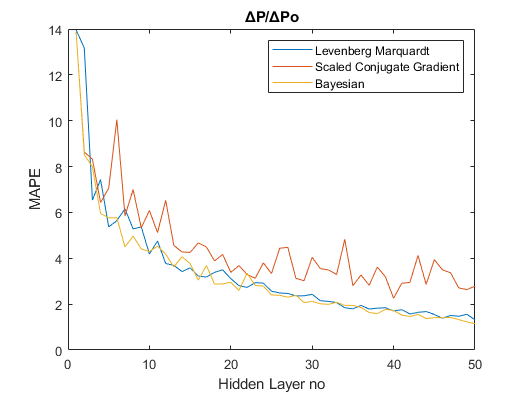

e=figure();
set(gca,'Box','on')
hold on;
plot(1:50,mape_train_lm(:,1));
plot(1:50,mape_train_scg(:,1));
plot(1:50,mape_train_bay(:,1))
xlabel('Hidden Layer no')
ylabel('MAPE')
title('ΔP/ΔPo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_P=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Pressure(mape).bmp');
saveas(gcf,plot_alg_train_P)
hold off;

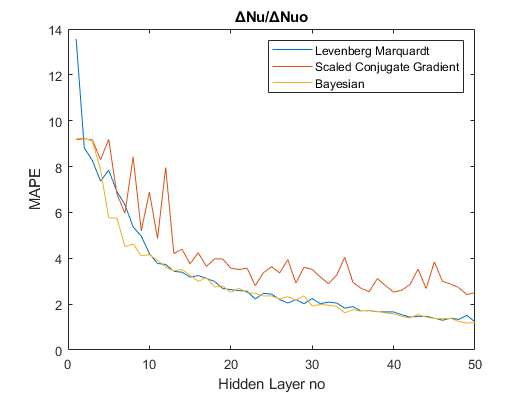


f=figure();
set(gca,'Box','on')
hold on;
plot(1:50,mape_train_lm(:,2));
plot(1:50,mape_train_scg(:,2));
plot(1:50,mape_train_bay(:,2))
xlabel('Hidden Layer no')
ylabel('MAPE')
title('ΔNu/ΔNuo')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian');
plot_alg_train_Nu=sprintf('D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison/all alg training data Nusselt(mape).bmp');
saveas(gcf,plot_alg_train_Nu);
hold off;

**Comparison Between Ann and Corelation**

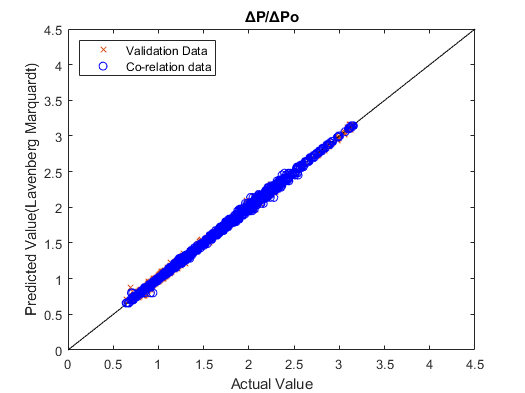

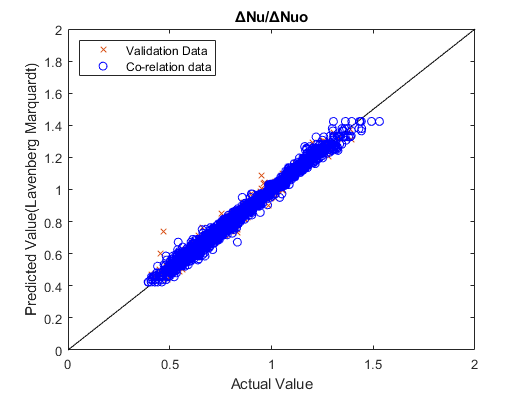

for i=1:2
    figure()
    plot(yValTrue_lm(i,:),yVal_lm(i,:),'x','color','#D95319');hold on;
    plot(0:5,0:5,'color','k');
    if i==1
        plot(yActual,yPredict_dt_p,'o','color','b')
    else
        plot(data_lr.delNudelNuo,yPredict_dt_nu,'o','color','b')
    end
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Validation Data','','Co-relation data','location','northwest')
    ylabel('Predicted Value(Lavenberg Marquardt)')
    xlabel('Actual Value')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/Comparison/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_LM_1)
    else
        Plot_LM_1=sprintf('D:/Matlab Drive/Research/Figure/Comparison/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_LM_1)
    end
end

table_2=[T_lm_val;T_scg_val;T_bay_val]

table_2 = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.015216    0.00048102    0.021932    0.99635    1.3334
    {'Nusselt ratio' }    0.012437    0.00036894    0.019208    0.98389    1.4704
    {'Pressure_ratio'}    0.036617     0.0026434    0.051414    0.97995    3.1823
    {'Nusselt ratio' }    0.026201     0.0013526    0.036777    0.94094    3.0984
    {'Pressure_ratio'}    0.013601    0.00038339     0.01958    0.99709    1.2247
    {'Nusselt ratio' }    0.011275    0.00030884    0.017574    0.98651    1.3346


writetable(table_2,'D:/Matlab Drive/Research/Table/Performence ( (All Algorithm) validation set.xlsx')
table_1=[T_lm_train;T_scg_train;T_bay_train]

table_1 = 6×6 table
           Var1             mae          mse          rmse        Rsq       mape 
    __________________    ________    __________    ________    _______    ______

    {'Pressure_ratio'}    0.015251    0.00047388    0.021769    0.99575    1.3288
    {'Nusselt ratio' }    0.011725    0.00030094    0.017348    0.98685    1.3744
    {'Pressure_ratio'}    0.038304     0.0029964     0.05474    0.97314    3.3152
    {'Nusselt ratio' }    0.026266     0.0013793    0.037139    0.93973    3.0742
    {'Pressure_ratio'}    0.013591    0.00037481     0.01936    0.99664    1.2109
    {'Nusselt ratio' }    0.010811    0.00024907    0.015782    0.98912    1.2673


writetable(table_1,'D:/Matlab Drive/Research/Table/Performence (All Algorithm) Training set.xlsx')

% sample=datasample(1:3276,300);
% sample_set=[yVal_lm' yValTrue_lm']';
% sample_set_lm=sample_set(:,sample)
% 
% x_sample=x';
% x_sample=x_sample(:,tr_lm.valInd);
% x_sample=x_sample(:,sample)
% 
% yPredict_dt_sample_p=predict(treeModel_p,x_sample')
% yPredict_dt_sample_nu=predict(treeModel_nu,x_sample')

testing_data_p;
testing_data_nu;
x(tr_lm.valInd,:);
Real_value=yValTrue_lm';
Predicted_value=yVal_bay';
yPredict_lr_sample_p=predict(linearModel_p,data_lr(tr_lm.valInd,:));
yPredict_lr_sample_nu=predict(linearModel_nu,data_lr(tr_lm.valInd,:));

sample=datasample(1:2730,150);

T=[testing_data_p(:,1:5),Real_value,Predicted_value,anfisoutput_p{3},anfisoutput_nu{3},yPredict_lr_sample_p,yPredict_lr_sample_nu]

T =    50.0000         0    1.5850    0.2000    0.2000    1.7255    0.9972    1.6972    0.9921    1.6799    1.0015    1.7315    0.8888
   50.0000         0    3.5650    0.2000    0.2000    1.7797    0.9961    1.7359    1.0144    1.7294    1.0009    1.7426    0.9021
   50.0000         0    4.5550    0.2000    0.2000    1.8119    0.9968    1.7625    1.0268    1.7541    1.0006    1.7495    0.9100
   50.0000         0   10.0000    0.2000    0.2000    2.0727    0.9990    1.9141    0.9855    1.9566    1.0059    1.8034    0.9698
   50.0000    0.5000    0.1000    0.2000    0.2000    1.7278    0.9069    1.7712    0.8925    1.6974    0.8521    1.6970    0.8159
   50.0000    0.5000    2.0800    0.2000    0.2000    1.7673    0.9057    1.8003    0.9136    1.7499    0.8937    1.7036    0.8251
   50.0000    0.5000    2.5750    0.2000    0.2000    1.7811    0.9128    1.8110    0.9227    1.7630    0.9041    1.7058    0.8280
   50.0000    0.5000    3.5650    0.2000    0.2000    1.8124    0.9270    1.836

T=T(sample,:)

T =   150.0000    0.5000    2.0800    0.2000    0.5000    0.9375    0.9087    0.9447    0.9195    0.9537    0.9504    1.0287    0.9535
  450.0000    2.0000    7.5250    0.3500    0.6500    0.8983    0.9084    0.8973    0.9001    0.9154    0.9539    1.0017    0.9349
   50.0000         0    4.5550    0.2000    0.5000    1.0119    1.0005    1.0146    1.0094    0.9929    1.0015    1.1056    1.0328
  200.0000    2.0000    8.0200    0.2000    0.5000    0.8340    0.8996    0.8249    0.9029    0.8475    0.8742    1.0958    0.8647
  450.0000         0    1.5850    0.2000    0.2000    1.1399    1.0132    1.1389    1.0186    1.1154    0.9913    1.5082    0.7619
  150.0000    0.5000   10.0000    0.2000    0.8000    1.0014    1.0002    0.9940    0.9976    1.0040    1.0026    0.8960    1.0003
  350.0000    2.0000    1.5850    0.6500    0.3500    1.3223    1.1078    1.3273    1.1075    1.1490    1.1778    1.1134    0.8792
  350.0000    1.0000    3.0700    0.6500    0.3500    1.1623    1.1034    1.138

## **COMPARISON OF ACCURACY**

**Pressure ratio comparison**

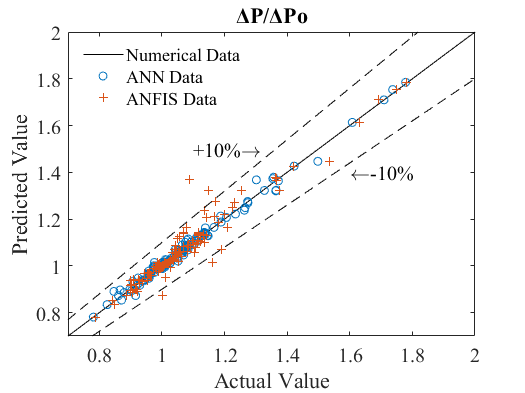

figure()
plot(0:5,0:5,'color','k'); hold on;
xlim([0.7 2])
ylim([0.7 2])
plot(T(:,8),T(:,6),'o','color','#0072BD')
xlabel('Actual Value')
ylabel('Predicted Value')
% plot(T(:,12),T(:,6),'o','color','b');
plot(T(:,10),T(:,6),'+','color',"#D95319");
x=0:5;
m1=(5.5/5);
y1=m1*x;
m2=(4.5/5);
y2=m2*x;
plot(x,y1,"LineStyle","--","Color","k")
plot(x,y2,"LineStyle","--","Color","k")
text(1.1,1.5,"+10%\rightarrow","FontSize",15,"FontName","Times")
text(1.6,1.4,"\leftarrow-10%","FontSize",15,"FontName","Times")
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
legend('Numerical Data','ANN Data','ANFIS Data','location','northwest',"Box","off");
title('ΔP/ΔPo');
Sample_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/ΔP÷ΔPo_200sample.jpg');
exportgraphics(gcf,Sample_plot_name)
hold off

**Nusselt ratio comparison**

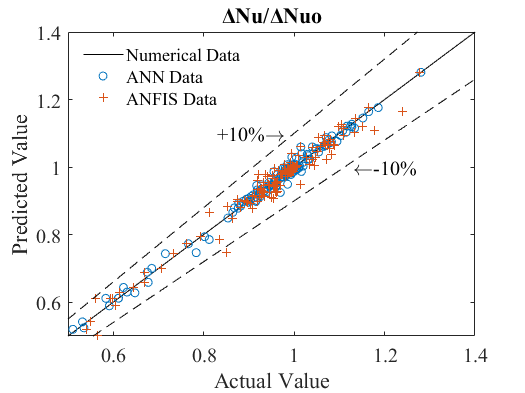

figure()
plot(0:5,0:5,'color','k'); hold on;
xlim([0.5 1.4])
ylim([0.5 1.4])
plot(T(:,9),T(:,7),'o','color','#0072BD');
xlabel('Actual Value')
ylabel('Predicted Value')
% plot(T(:,13),T(:,7),'o','color','b');
plot(T(:,11),T(:,7),'+','color','#D95319');
plot(x,y1,"LineStyle","--","Color","k")
plot(x,y2,"LineStyle","--","Color","k")
text(0.83,1.1,"+10%\rightarrow","FontSize",15,"FontName","Times")
text(1.13,1,"\leftarrow-10%","FontSize",15,"FontName","Times")
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
legend('Numerical Data','ANN Data','ANFIS Data','location','northwest',"Box","off");
title('ΔNu/ΔNuo');
Sample_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/ΔNu÷ΔNuo_200sample.jpg');
exportgraphics(gcf,Sample_plot_name)
hold off

## RELATIVE ERROR

**Nusselt ratio**

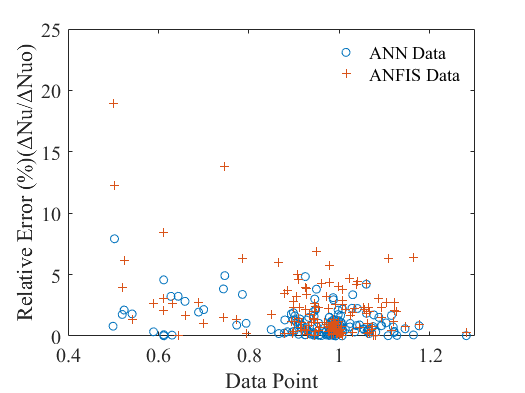

R_er_p_ann=Relativeerror(T(:,7),T(:,9));
R_er_p_anfis=Relativeerror(T(:,7),T(:,11));
% R_er_p_dt=R_error(T(:,7),T(:,13));
plot(T(:,7),R_er_p_ann,"o",'color','#0072BD'); hold on
plot(T(:,7),R_er_p_anfis,'+','color','#D95319')
% plot(T(:,6),R_er_p_dt,'o','color','b')
xlim([0.4 1.3])
ylim([0 25])
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Data Point')
ylabel('Relative Error (%)(ΔNu/ΔNuo)')
legend('ANN Data','ANFIS Data','location','northeast',"Box","off")
Relative_err_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/Relative error Nu 200sample.jpg');
exportgraphics(gcf,Relative_err_plot_name)
hold off

**Pressure Ratio**

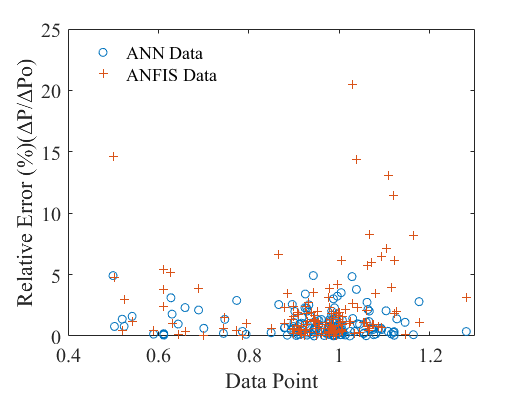

R_er_p_ann=Relativeerror(T(:,6),T(:,8));
R_er_p_anfis=Relativeerror(T(:,6),T(:,10));
% R_er_p_dt=R_error(T(:,7),T(:,13));
plot(T(:,7),R_er_p_ann,"o",'color','#0072BD'); hold on
plot(T(:,7),R_er_p_anfis,'+','color','#D95319')
% plot(T(:,6),R_er_p_dt,'o','color','b')
xlim([0.4 1.3])
ylim([0 25])
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Data Point')
ylabel('Relative Error (%)(ΔP/ΔPo)')
legend('ANN Data','ANFIS Data','location','northwest',"Box","off")
Relative_err_plot_name=sprintf('D:/Matlab Drive/Research/Figure/Comparison/without corr/Relative error P 200sample.jpg');
exportgraphics(gcf,Relative_err_plot_name)
hold off

T_nu_disp_bar=T_nu(2:6,:)

T_nu_disp_bar = 5×5 table
      mae          mse         rmse        Rsq       mape 
    ________    _________    ________    _______    ______

    0.035986    0.0031656    0.056263    0.86177    4.3408
    0.023224     0.001326    0.036415     0.9421    2.8696
    0.023256    0.0011029     0.03321    0.95184    2.7545
     0.02273    0.0013051    0.036127    0.94301    2.8056
    0.027153    0.0014988    0.038714    0.93455    3.2515


T_p_disp_bar=T_p(2:6,:)

T_p_disp_bar = 5×5 table
      mae          mse          rmse        Rsq       mape 
    ________    __________    ________    _______    ______

    0.027898     0.0019917    0.044629    0.98489    2.3699
    0.021553    0.00095006    0.030823    0.99279     1.923
    0.022763     0.0014886    0.038583    0.98871    2.0091
    0.021705    0.00096956    0.031138    0.99264     1.974
     0.02782     0.0019949    0.044665    0.98487    2.3642


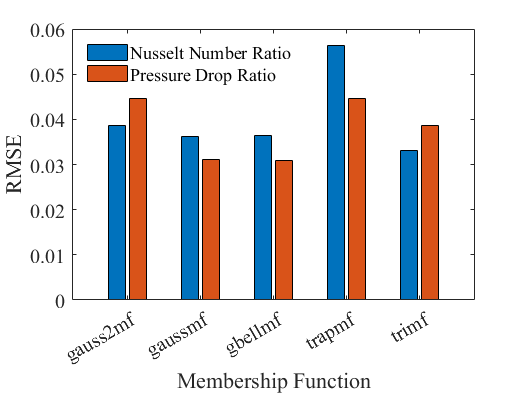

T_bar_anfis=array2table(cat(2,table2array(T_nu_disp_bar),table2array(T_p_disp_bar)));
bar(categorical(T_nu_disp{1:5,1}),T_bar_anfis{1:5,{'Var3','Var8'}})
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('Membership Function')
ylabel('RMSE')
legend("Nusselt Number Ratio","Pressure Drop Ratio","Location","northwest","Box","off");
name_bar_anfis=sprintf("D:/Matlab Drive/Research/Fuzzy/Figure/RMSE.jpg");
exportgraphics(gcf,name_bar_anfis)

min(rms_val_lm);
min(rms_val_scg);
min(rms_val_bay);
name_min_error={'Lavenberg','Bayesian',"SCG"};
T_min_error_=array2table(cat(1,min(rms_val_lm),min(rms_val_bay),min(rms_val_scg)),"VariableNames",{'Pressure Drop Ratio','Nusselt Number Ratio'});
T_min_error=cat(2,name_min_error',T_min_error_)

T_min_error = 3×3 table
       Var1        Pressure Drop Ratio    Nusselt Number Ratio
    ___________    ___________________    ____________________

    "Lavenberg"         0.020491                0.016638      
    "Bayesian"           0.01868                0.016807      
    "SCG"               0.036334                0.029669      


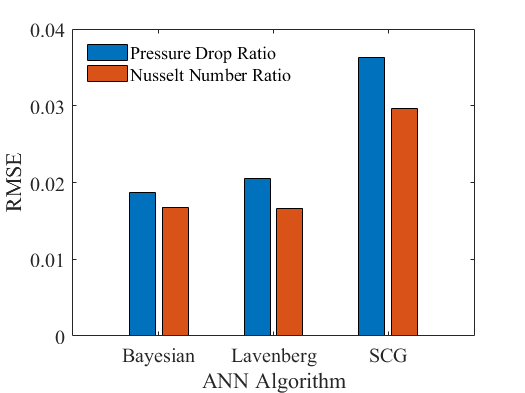

bar(categorical(T_min_error{:,1}),T_min_error{:,{'Pressure Drop Ratio','Nusselt Number Ratio'}})
set(gca,...
'Units','normalized',...
'FontUnits','points',...
'FontWeight','normal',...
'FontSize',15,...
'FontName','Times')
xlabel('ANN Algorithm')
ylabel('RMSE')
legend("Pressure Drop Ratio","Nusselt Number Ratio","Location","northwest","Box","off");
name_bar_ann=sprintf("D:/Matlab Drive/Research/Figure/All Algorithm optimization comparison (new)/RMSE.jpg");
exportgraphics(gcf,name_bar_ann)